# Controllers

Generate and edit controllers without the simulink sampling code

#### Startup

run("data/LabStartup.mlx");
run("data/quanser_aero_parameters.m");
run("data/quanser_aero_state_space.m");
Gss = minreal(ss(A,B,C,D));
G = Gss.NominalValue;

Delta_1 = 0;
Delta_2 = 0;

#### Inverse

G_inv = zpk(inv(Gss)); % improper, need to add HF poles
HF_pole = 100; % keep HF poles below 300
G_inv_appx = 1/(s/HF_pole+1)^2*G_inv;
wc = 5;
s = tf('s');
L_des = wc/s*eye(2);
W2 = G_inv_appx; % precompensator
K_ls = minreal(tf(L_des*W2)); % controller is just the loopshape
K_ls = ss(K_ls);
size(K_ls)

State-space model with 2 outputs, 2 inputs, and 5 states.


#### H2

Wp2 = makeweight(100,5,1/2)/(s/HF_pole+1)*eye(2);
Wu2 = tf([1],[18])*eye(2);
% generate sysic plant model
systemnames = 'G Wp2 Wu2';
inputvar = '[r{2};u{2}]';
outputvar = '[Wp2;Wu2;r-G]';
input_to_G = '[u]';
input_to_Wu2 = '[u]';
input_to_Wp2 = '[r-G]';
cleanupsysic = 'yes';
P2 = sysic;
% do synthesis
[K2,CL2,GAM2] = h2syn(P2,2,2);
K = minreal(K2);
size(K2)

State-space model with 2 outputs, 2 inputs, and 8 states.


#### H-inf

G_vec = usample(Gss,50);
[P,info] = ucover(G_vec,G,[2,2]);
sampled_weights = inv(G)*G_vec - eye(2);
WI = info.W1;
W_I_Pitch = WI(1,1);
W_I_Yaw = WI(2,2);
Wpi = makeweight(100,5,1/2)*eye(2);
Wui = tf([1],[25])*eye(2);
% generate sysic model
systemnames = 'G Wpi Wui WI';
inputvar = '[ud{2};r{2};u{2}]';
outputvar = '[WI;Wpi;Wui;r-G]';
input_to_G = '[u+ud]';
input_to_Wui = '[u]';
input_to_Wpi = '[r-G]';
input_to_WI = '[u]';
cleanupsysic = 'yes';
Pi = sysic;
% do synthesis
[Ki,CLi,GAMi] = hinfsyn(Pi,2,2);
Ki = minreal(Ki);
size(Ki)

State-space model with 2 outputs, 2 inputs, and 10 states.


#### Reduced Mu-syn

Wpm = makeweight(100,5,1/2)*eye(2);
Wum = tf([1],[18])*eye(2);
% generate sysic model
systemnames = 'Gss Wpm Wum';
inputvar = '[r{2};u{2}]';
outputvar = '[Wpm;Wum;r-Gss]';
input_to_Gss = '[u]';
input_to_Wum = '[u]';
input_to_Wpm = '[r-Gss]';
cleanupsysic = 'yes';
Pm_unc = sysic;
% do synthesis              
[Km,CLm,GAMm] = dksyn(Pm_unc,2,2);
% reduce order via truncation to match H-inf controller
size(minreal(Ki))

Undefined function or variable 'Ki'.

%modelReducer(Km)
%% Reduce LTI model order using balanced truncation
System = Km; % Define System to reduce
Order = 10;
% Create option set for balred command
Options = balredOptions();
% Compute reduced order approximation
ReducedSystem = balred(System,Order,Options); 
% Create comparison plot
Km = ReducedSystem;
size(Km)

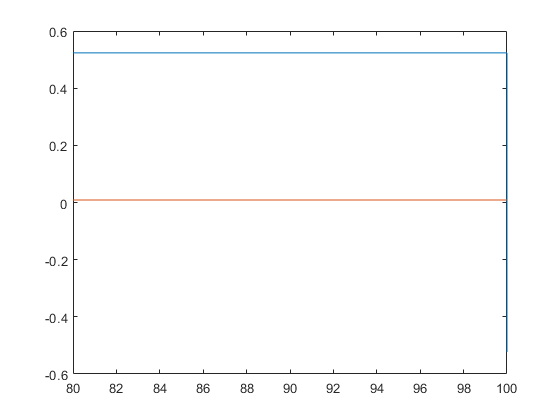

plot(pitch_samples.time,pitch_samples.signals.values)